## clean up and add path

clear
close all
clc
addpath(genpath('..\..'))%% reach the functions and filters

## path data generation

dt = 0.1;
vx = 1;
vy = 0;

x_c = 0;
y_c = 7;

i = 1;
while x_c <10
    path(i,:) = [x_c, y_c];
    x_c = x_c + vx*dt;
    y_c = y_c + vy*dt + randn*0.1;
    i = i + 1;
end

## doing smoothing while reading sensor

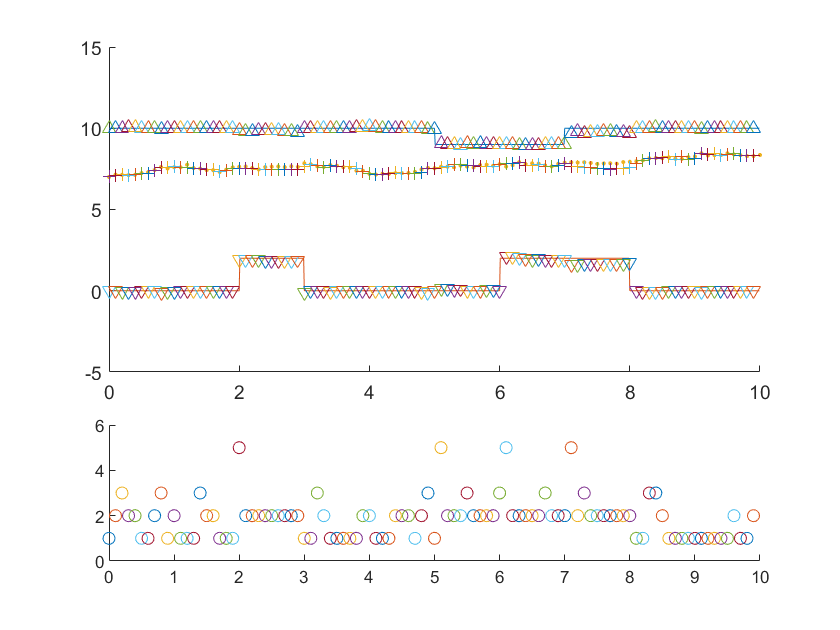

% define the environment
s = sensors(@roof,@terran,path);
% define the filter
M = 1000; % number of particles
x0 = [ones([M,1])*7,ones([M,1])*10,ones([M,1])*0]; % initial states

modeln = 5;
filter = cell([1,modeln]);
for modeli = 1:modeln
    eval(['filter{', num2str(modeli), '} = PfBs(x0,@RndTr', num2str(modeli), ',@LiOb);'])
end
% filtering loop

figure
subplot(3,1,1:2)
s.plot()
hold on
while s.hasNext()
    [d, x_c] = s.read();
    y = [d.infraredup, d.infrareddown];
    for modeli = 1: modeln
        [x_hat(modeli,:), ML(modeli)] = filter{modeli}.estimate(y); % doing filtering
    end
    
    m_ind = 1:modeln;
    subplot(3,1,3)
    hold on
    plot(x_c, m_ind(ML==max(ML)), 'o')
    
    x_hat = weighted_mean_nan(x_hat, ML);
    subplot(3,1,1:2)
    plot(x_c, x_hat(1),'+')
    plot(x_c, 10 + x_hat(2),'^')
    plot(x_c, x_hat(3),'v')
    ylim([-5,15])
    mm_resample(filter)
end

# discussions

The observation model is very obvious, and there is not much to talk about it.

There are 2 kinds of state transitions models:

- self coordinated, focus on the change of the states

- world coordinated, focus on the absolute value of the states

While we are estimating 3 states with only the differences are observed. It is impossible to remove the accumulated error with the 1st kind of transition alone. However, utilizing the history states can give a better estimation. The best result is achieved by combining the two kinds.

# Model functions

## room description function

function y = roof(x)
y = 10*ones(size(x));
y(x>5 & x<7) = 9;
end
function y = terran(x)
y = zeros(size(x));
y(x>2 & x<3) = 2;
y(x>6 & x<8) = 2;
end

## model

### ovservation

$y_1$: upward distance measure

$y_2$: downward distance measure

### **states**

$x_1$: height of the drone

$x_2$: displacement of roof, upward

$x_3$: displacement of terrain, downward

### observation model


$$y_1 = H + x_2 - x_1+\epsilon_1,\ 
\epsilon_1 \sim \mathcal{N}(0,\sigma_1^2)$$



$$y_2 = x_1 - x_3 +\epsilon_2,\ 
\epsilon_2 \sim \mathcal{N}(0,\sigma_1^2)$$


### observarion likelihood function

input:

y: 1*Dy: one observation, Dy=2

x: N*Dx: N state vectors, Dx=3

output:

p: N*1: likelihood vector

function p = LiOb(y,x)
% observation likelihood

% parameter
H = 10; % known
sig1 = 0.1;
sig2 = 0.1;
% passing
N = size(x, 1);
% calculate the likelihood saperately
p1 = normpdf(H + x(:,2) - x(:,1), y(1), sig1);
p2 = normpdf(x(:,1) - x(:,3), y(2), sig2);
p = p1 .* p2;
end

### Transition model

for all the following functions:

input:

x: N*Dx: N state vectors, Dx=3

randomOn: 0 or 1

    if 0, returns prediction without noise

    if 1, returns noisy transition states

output:

x: same as input

#### model1: no obstical at all


$$x_1 = x_1 + \epsilon\\
x_{2,3} = 0$$


function x = RndTr1(x,randomOn)
% state ransition function 1
% keep the same
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2:3) = 0;
end

#### model2: keep the same


$$x_1 = x_1 + \epsilon\\
x_2 = x_2\\
x_3 = x_3$$


function x = RndTr2(x,randomOn)
% state ransition function 1
% keep the same
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
end

#### model3: random walk


$$x_1 = x_1 + \epsilon_1\\
x_{2,3} = x_{2,3} + \epsilon_2$$


function x = RndTr3(x,randomOn)
% state ransition function 2
% random walk
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
sig_wall = 0.1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2:3) = x(:,2:3) + randn(size(x(:,2:3)))*sig_wall*randomOn;
end

#### model4: uniform 


$$x_1 = x_1 + \epsilon\\
x_2 = \mathcal{U}(r2)\\
x_3 = \mathcal{U}(r3)$$


function x = RndTr4(x,randomOn)
% state ransition function 1
% uniform
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
rangeup = [1,-5];
rangedown = [-1,5];
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2) = ( rand(size(x(:,2))) * range(rangeup) + min(rangeup))*randomOn;
x(:,3) = ( rand(size(x(:,3))) * range(rangedown) + min(rangedown))*randomOn;
end

#### model5: exp obsticles 


$$x_1 = x_1 + \epsilon\\
-x_2 \sim Ex(\mu2)\\
x_3 \sim Ex(\mu3)$$


function x = RndTr5(x,randomOn)
% state ransition function 1
% uniform
if nargin == 1
    randomOn = 1;
end
% parameters
sig_drone = 0.1;
muup = 1;
mudown = 1;
% transition
x(:,1) = x(:,1) + randn(size(x(:,1)))*sig_drone*randomOn;
x(:,2) = -exprnd(muup,size(x(:,2)))*randomOn;
x(:,3) = exprnd(mudown,size(x(:,3)))*randomOn;
end

### Mixture model

function x = RndTr(x,randomOn)
% mixture model
% mixture weights
w = [0,3,1,6,2];
if nargin == 1
    randomOn = 1;
end
model = datasample(1:5,1,'weights',w );
eval(['x = RndTr',num2str(model),'(x,randomOn);'])
end
